%% データの読み込み
filename = ['../../../materials/db250424.mat'];
dummy = ['load ' filename];
eval(dummy);

function data = cell2str(input)
    cell = table2cell(input);
    str = cell{1};               % 角かっこ付きの文字列
    str = strrep(str, '[', '');
    str = strrep(str, ']', '');
    data = str2double(split(str, ','));  % 文字列を分割し、数値配列に変換
end

tmp=dataJitterFreq(29,1:end);
data = cell2str(tmp(1,7));  % 文字列を分割し、数値配列に変換
plot(data, 'Color',[0,135,255]/255,'LineWidth', 2);
legend('Open', 'Close')

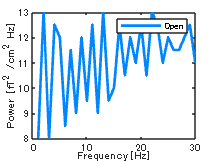

xlabel('Frequency [Hz]');
ylabel('Power [fT^2 /cm^2 Hz]');


filename = ['../../../materials/db250424.mat'];
dummy = ['load ' filename];
eval(dummy);
table = sortrows(dataJitterFreq, 1)

table = 115×14 table
    user_id    measurement_count      start_datetime          end_datetime        brightness                            trial_response                                                                                  trial_freq                                                                                                                          trial_rt                                                                    trial_num                       condition_high_freq_log                             condition_high_resp_log                           condition_low_freq_log                           condition_low_resp_log                                  condition_order                        
    _______    _________________    ___________________    ___________________    __________    _______________________________________________________________    _________________________________________________________________________________________________________________

function freq = get_freq(id, table)
    tmp=table(id,1:end);
    data = cell2str(tmp(1,7));  % 文字列を分割し、数値配列に変換
    high_freq=cell2str(tmp(1,10));
    high_resp=cell2str(tmp(1,11));
    low_freq=cell2str(tmp(1,12));
    low_resp=cell2str(tmp(1,13));
    
    if high_resp(end) == 0
        high_last = high_freq(end) + 0.5;
    else
        high_last = high_freq(end) - 0.5;
    end
    if low_resp(end) == 0
        low_last = low_freq(end) + 0.5;
    else
        low_last = low_freq(end) - 0.5;
    end
    
    freq = (high_last + low_last) / 2;
end
get_freq(29,table)

ans = 10.5000

res = arrayfun(@(x) get_freq(x, table), 4:7);
hold off;

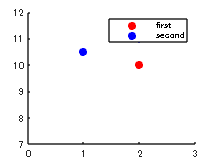

scatter([1,2],res(1:2), 'filled', 'MarkerFaceColor','red');
hold on;
scatter([1,2],res(3:4), 'filled', 'MarkerFaceColor','blue');
axis([0 3 7 12]);  %軸の範囲設定
legend('first', 'second');
hold off;

sum = arrayfun(@(x) get_freq(x, table), 4:7) + arrayfun(@(x) get_freq(x, table), 9:12) + arrayfun(@(x) get_freq(x, table), 14:17) + arrayfun(@(x) get_freq(x, table), 20:23)  +arrayfun(@(x) get_freq(x, table), 24:27) + arrayfun(@(x) get_freq(x, table), 35:38) + arrayfun(@(x) get_freq(x, table), 39:42) + arrayfun(@(x) get_freq(x, table), 44:47) + arrayfun(@(x) get_freq(x, table), 48:51) + arrayfun(@(x) get_freq(x, table), 52:55) + arrayfun(@(x) get_freq(x, table), 69:72) + arrayfun(@(x) get_freq(x, table), 73:76) + arrayfun(@(x) get_freq(x, table), 78:81) + arrayfun(@(x) get_freq(x, table), 86:89) + arrayfun(@(x) get_freq(x, table), 93:96) + arrayfun(@(x) get_freq(x, table), 112:115);
sum = sum / 16;
hold off;

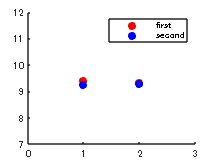

scatter([1,2],sum(1:2), 'filled', 'MarkerFaceColor','red');
hold on;
scatter([1,2],sum(3:4), 'filled', 'MarkerFaceColor','blue');
axis([0 3 7 12]);  %軸の範囲設定
legend('first', 'second');
hold off;

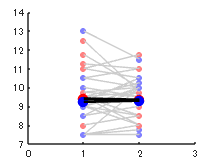

% written by chatGPT
% 定義された範囲
ranges = [4 7; 9 12; 14 17; 20 23; 24 27; 35 38; 39 42; 44 47;
48 51; 52 55; 69 72; 73 76; 78 81; 86 89; 93 96; 112 115];

% 各範囲から得られるデータを保持（16×4 の行列）
individual_results = zeros(size(ranges, 1), 4);

% 各範囲ごとに get_freq を適用
for i = 1:size(ranges,1)
    idx = ranges(i,1):ranges(i,2);
    individual_results(i,:) = arrayfun(@(x) get_freq(x, table), idx);
end

% プロット準備
hold off;


% 個別データをプロット（薄い色）と対応線の描画
for i = 1:size(individual_results,1)
    y1 = individual_results(i,1); % 1番 (x=1)
    y2 = individual_results(i,2); % 2番 (x=2)
    y3 = individual_results(i,3); % 3番 (x=1)
    y4 = individual_results(i,4); % 4番 (x=2)
    
    % 個別点（薄い色）
    scatter(1, y1, 20, [1 0.5 0.5], 'filled'); hold on;
    scatter(2, y2, 20, [1 0.5 0.5], 'filled');
    scatter(1, y3, 20, [0.5 0.5 1], 'filled');
    scatter(2, y4, 20, [0.5 0.5 1], 'filled');
    
    % 対応線
    plot([1 2], [y1 y2], 'Color', [0.8 0.8 0.8]);  % gray line
    plot([1 2], [y3 y4], 'Color', [0.8 0.8 0.8]);
end

% 各列の平均を計算
mean_col1 = mean(individual_results(:,1)) % x=1, 赤

mean_col1 = 9.4062

mean_col2 = mean(individual_results(:,2)) % x=2, 赤

mean_col2 = 9.3438

mean_col3 = mean(individual_results(:,3)) % x=1, 青

mean_col3 = 9.2344

mean_col4 = mean(individual_results(:,4)) % x=2, 青

mean_col4 = 9.2969


% 平均点のプロット（濃い色）
scatter(1, mean_col1, 60, 'red', 'filled');
scatter(2, mean_col2, 60, 'red', 'filled');
scatter(1, mean_col3, 60, 'blue', 'filled');
scatter(2, mean_col4, 60, 'blue', 'filled');

% 平均点同士を黒の線で結ぶ
plot([1 2], [mean_col1 mean_col2], 'k-', 'LineWidth', 2); % 赤系列（列1と2）
plot([1 2], [mean_col3 mean_col4], 'k-', 'LineWidth', 2); % 青系列（列3と4）

axis([0 3 7 14]);
hold off;